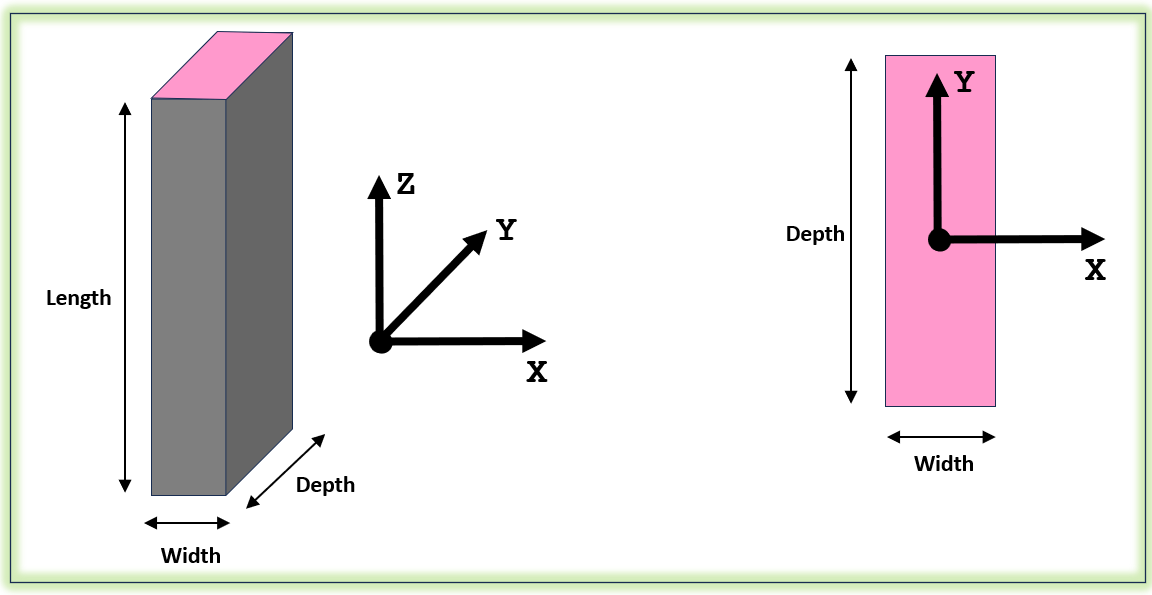

function col_OBJ = bh_create_column_OBJ( opts_T )
    arguments
        opts_T.Width       (1,1) double {mustBePositive} = 1    % (m)      - Width  
        opts_T.Depth       (1,1) double {mustBePositive} = 1    % (m)      - Height 
        opts_T.Length      (1,1) double {mustBePositive} = 1    % (m)      - Length 
        opts_T.density     (1,1) double {mustBePositive} = 7830 % (kg/m^3) - density of steel
        opts_T.E_GPa_Young (1,1) double {mustBePositive} = 200  % (GPa)    - Youngs Modulus for steel
        opts_T.v_Poisson   (1,1) double {mustBePositive} = 0.3  % (-)      - Poisson's Ratio for steel    
    end
    
    % create the shaft OBJECT
    col_OBJ = bh_flex_column_CLS( opts_T.Width, opts_T.Depth, opts_T.Length, opts_T.density, opts_T.E_GPa_Young, opts_T.v_Poisson);
    
end % function bh_create_shaft_OBJ()